# Lesson II.6:   The Four Fundamental Subspaces (F24)

The four fundamental subspaces of an $m\times n$ matrix $A$ are considered here.   Key results of this lesson include the standard methods for finding bases for these spaces.  First, we recall some pertinent facts regarding the concept of vector space.

**Vector Spaces.**

- By definition a vector space is a nonempty set of vectors closed under the formation of linear combinations.  In symbols $V\subset{\mathbb R}^n~(\text{or }~{\mathbb C}^n)$ is a vector space if and only if $V\ne\emptyset$ and $\{{\bf x}_1,\dots,{\bf x}_p\}\subset V\quad\Rightarrow\quad\alpha_1{\bf x}_1+\cdots+\alpha_p{\bf x}_p\in V$.   

- A vector space is an affine set that contains the origin.

figII6a()

- A vector space (in ${\mathbb R}^n$ or ${\mathbb C}^n$) is the solution set of a homogeneous linear system:   $A{\bf x}={\bf 0}$.   Such a linear system gives an *implicit representation* of the vector space.

- Every vector space (in ${\mathbb R}^n$ or ${\mathbb C}^n$) is the span of a finite set of vectors.    Such a spanning set gives an *explicit representation* of a vector space.    

- A basis for a vector space (a linearly independent spanning set) provides a explicit representation for vectors in the vector space that is moreover unique (only one set of coefficients can be used to represent any vector in the vector space).

- A subspace is a vector space that is a subset of another vector space.    Because every vector space is a subspace (of itself if nothing else) and every subspace is a vector space, there is no substantial difference between these two terms.    In practice, the term ``subspace" is used to alert the reader to the fact that there are two vector spaces of interest (though possibly equal to each other) and that their relationships are under consideration.

- The intersection of a collection of subspaces (all subsets of a common vector space) is again a subspace.    This fact has been on display from the beginning of our consideration of linear systems:   Every nontrivial equation of a homogeneous linear system defines a hyperplane containing the origin, and the solution set of the system is the intersection of these hyperplanes.

**The null space****.**   The ***null space*** of an $m\times n$ matrix $A$, written $\text{nul}(A)$, consists of the solutions of the homogeneous equation $A{\bf x}=\bf 0$.    Notice $\text{nul}(A)\subset{\mathbb R}^n$.   The set of basic solutions of $A$ is a spanning set.    Moreover, the basic solutions are linearly independent (argument reviewed in Appendix II.6A), so they form a basis for $\text{null}(A)$.   The dimension of the null space is the nullity $\nu$ of the matrix $A$ (the number of columns without pivots).   

_________________________________________________________________

**Example II.6.1a:**  Consider the matrix $A=\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]$ with $\text{rref}(A)=\left[\matrix{1 & 0 & -1 \cr 0 & 1 & 2 \cr 0&0&0}\right]$.   There is one free variable $x_3$ (the third column has no pivot) and the corresponding basic solution is ${\bf v}_1=\left[\matrix{1\cr-2\cr1}\right]$.    A basis for $\text{nul}(A)$ is the singleton set containing ${\bf v}_1$.  Finally, $\text{dim}\big(\text{nul}(A)\big)=1=\nu=n-r$ where $r=\text{rank}(A)=2$.

**Example II.6.1b:   **Consider the matrix $A=\left[ \matrix{2 & 2 & 2\cr 4 & 4 & 4}\right]$ with $\text{rref}=\left[\matrix{1&1 &1\cr0&0&0}\right]$.   There are two free variables, $x_2$ and $x_3$, and the corresponding basic solutions are ${\bf v}_1=\left[\matrix{-1\cr1\cr0}\right]$ and ${\bf v}_2=\left[\matrix{-1\cr0\cr1}\right]$.   A basis for $\text{nul}(A)$ is the two-element set $\{{\bf v}_1,{\bf v}_2\}$.    Finally, $\text{dim}\big(\text{nul}(A)\big)=2=\nu=n-r$ where $r=\text{rank}(A)=1$.

**Example II.6.1c:**   Consider the matrix $A=\left[\matrix{1 & 0\cr0 & 1}\right]$ which is already in reduced row-echelon form.    Since all columns have pivots the only solution of $A{\bf x}={\bf 0}$ is ${\bf x}={\bf 0}$.   Hence, $\text{nul}(A)=\{\bf 0\}$ and the basis is the empty set $\emptyset$ (recall $\text{Span}(\emptyset)=\{\bf0\}$).   Finally, $\dim\big(\text{nul}(A)\big)=0=\nu=n-r$ where $r=\text{rank}(A)=2$.

**Example II.6.1d:**   Consider the matrix $A=\left[\matrix{0 & 0\cr0 & 0}\right]$ which is already in reduced row-echelon form. There are two free variables, $x_1$ and $x_2$, and the corresponding basic solutions are ${\bf v}_1=\left[\matrix{1\cr0}\right]$and ${\bf v}_2=\left[\matrix{0\cr1}\right]$.  A basis for $\text{nul}(A)$ is the two-element set $\{{\bf v}_1,{\bf v}_2\}$.    Finally, $\text{dim}\big(\text{nul}(A)\big)=2=\nu=n-r$ where $r=\text{rank}(A)=0$.

___________________________________________________________________

**The column space****.  ** The ***column space*** of a real $m\times n$ matrix $A$, written $\text{col}(A)$, consists of the span of the columns of $A$.   Notice $\text{col}(A)\subset{\mathbb R}^m$.   The pivot columns of $A$ are a basis for $\text{col}(A)$ (see Appendix II.6B for more details).   The dimension of the column space is the rank $r$ of the matrix $A$ (the number of columns with pivots).  

_________________________________________________________________________________

**Example II.6.2a:**  Consider the matrix $A=\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]$ with $\text{rref}(A)=\left[\matrix{1 & 0 & -1 \cr 0 & 1 & 2 \cr 0&0&0}\right]$.   The two-element set of the pivot columns $\left\{\left[\matrix{1\cr4\cr7}\right],\left[\matrix{2\cr5\cr8}\right]\right\}$is a basis of $\text{col}(A)$.   Hence, $\text{dim}\big(\text{col}(A)\big)=2=r$ where $r=\text{rank}(A)=2$.

**Example II.6.2b:   **Consider the matrix $A=\left[ \matrix{2 & 2 & 2\cr 4 & 4 & 4}\right]$ with $\text{rref}=\left[\matrix{1&1 &1\cr0&0&0}\right]$.   The singleton set containing the pivot column $\left\{\left[\matrix{2\cr4}\right]\right\}$is a basis of $\text{col}(A)$.   Hence, $\text{dim}\big(\text{col}(A)\big)=1=r$ where $r=\text{rank}(A)=1$.

**Example II.6.2c:**   Consider the matrix $A=\left[\matrix{1 & 0\cr0 & 1}\right]$ which is already in reduced row-echelon form.    The two-element set of the pivot columns $\left\{\left[\matrix{1\cr0}\right],\left[\matrix{0\cr1}\right]\right\}$is a basis of $\text{col}(A)$.    Hence, $\text{dim}\big(\text{col}(A)\big)=2=r$ where $r=\text{rank}(A)=2$. 

**Example II.6.2d:**   Consider the matrix $A=\left[\matrix{0 & 0\cr0 & 0}\right]$ which is already in reduced row-echelon form. There are no pivot columns.   The column space is the trivial subspace $\{\bf0\}$ which has the empty set $\emptyset$ as its basis.  Hence, $\text{dim}\big(\text{col}(A)\big)=0=r$ where $r=\text{rank}(A)=0$.

_________________________________________________________________________________

**The row space****.  **The ***row space ***of a real $m\times n$ matrix $A$, written $\text{row}(A)$, is the column space of$A^T$:  $\text{row}(A)=\text{col}(A^T)$.  That is, the row space consists of all linear combinations of the rows of $A$ (transposed to become columns). Notice that $\text{Row}(A)\subset{\mathbb R}^n$.  While a basis could be found through computing $\text{rref}(A^T)$, it is generally more convenient to use the nonzero rows of $\text{rref}(A)$ (transposed to be columns).  (This choice for the basis is further explained in Appendix II.6C.)  The dimension of the column space is $r=\text{rank}(A^T)=\text{rank}(A)$.

_________________________________________________________________________________

**Example II.6.3a:**  Consider the matrix $A=\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]$ with $\text{rref}(A)=\left[\matrix{1 & 0 & -1 \cr 0 & 1 & 2 \cr 0&0&0}\right]$.   Taking the transpose of the nonzero rows of $\text{rref}(A)$ gives a two-element set  $\left\{\left[\matrix{1\cr0\cr-1}\right],\left[\matrix{0\cr1\cr2}\right]\right\}$which is a basis of $\text{row}(A)$.   Hence, $\text{dim}\big(\text{row}(A)\big)=2=r$ where $r=\text{rank}(A)=2$.

**Example II.6.3b:   **Consider the matrix $A=\left[ \matrix{2 & 2 & 2\cr 4 & 4 & 4}\right]$ with $\text{rref}=\left[\matrix{1&1 &1\cr0&0&0}\right]$.   Taking the transpose of the nonzero rows of $\text{rref}(A)$ gives $\left\{\left[\matrix{1\cr1\cr1}\right]\right\}$which is a basis of $\text{row}(A)$.   Hence, $\text{dim}\big(\text{row}(A)\big)=1=r$ where $r=\text{rank}(A)=1$.

**Example II.6.3c:**   Consider the matrix $A=\left[\matrix{1 & 0\cr0 & 1}\right]$ which is already in reduced row-echelon form.    Taking the transpose of the nonzero rows of $\text{rref}(A)$ gives $\left\{\left[\matrix{1\cr0}\right],\left[\matrix{0\cr1}\right]\right\}$which is a basis of $\text{row}(A)$.    Hence, $\text{dim}\big(\text{col}(A)\big)=2=r$ where $r=\text{rank}(A)=2$. 

**Example II.6.3d:**   Consider the matrix $A=\left[\matrix{0 & 0\cr0 & 0}\right]$ which is already in reduced row-echelon form.  There are no nonzero rows.   The row space is the trivial subspace $\{\bf0\}$ which has the empty set $\emptyset$ as its basis.  Hence, $\text{dim}\big(\text{row}(A)\big)=0=r$ where $r=\text{rank}(A)=0$.

_________________________________________________________________________________

**The left null space****.**   The ***left null space*** of the real $m\times n$ matrix $A$, written $\text{nul}(A^T)$, is the null space of$A^T$.   Notice $\text{nul}(A^T)\subset{\mathbb R}^m$.  The name of this space is motivated by taking the transpose of the equation $A^T{\bf z}={\bf 0}$ which gives ${\bf z}^T A={\bf 0}^T$.   That is, a vector in the left null space has the property that when its transpose is multiplied on the left side of $A$ the result is a zero (row) vector.   The standard process for finding a basis for the left null space is the most complicated of the four:    The $m\times n$ matrix $A$ is first augmented by the $m\times m$ identity to obtain $\left[\matrix{A&I}\right]$.   We then find the reduced row-echelon form of this augmented matrix which gives the reduced row-echelon form of $A$ augmented by an $m\times m$ matrix $W$: $\left[\matrix{\text{rref}(A) & W}\right]$.   The basis for $\text{nul}(A^T)$ consists of the last $m-\text{rank}(A)$ columns of $W^T$.   Notice, that these columns were rows next to the rows of zeros in $\text{rref}(A)$.    An explanation for this procedure is found in Appendix II.6D.   The dimension of the left null space is $m-r$ where $r=\text{rank}(A).$

_________________________________________________________________________________

**Example II.6.4a:**  Consider the matrix $A=\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]$ with $\text{rref}([A~I])=\left[\matrix{1 & 0 & -1 & 0 & -8/3 & 5/3 \cr 0 & 1 & 2& 0 & 7/3 & -4/3 \cr 0&0&0 & 1 & -2 & 1}\right]$.   The transpose of the row next to the one row of zeros in $\text{rref}(A)$ gives  $\left\{\left[\matrix{1\cr-2\cr1}\right]\right\}$as a basis of $\text{nul}(A^T)$.   Hence, $\text{dim}\big(\text{nul}(A^T)\big)=1=m-r=3-2$.

**Example II.6.4b:   **Consider the matrix $A=\left[ \matrix{2 & 2 & 2\cr 4 & 4 & 4}\right]$ with $\text{rref}([A~I])=\left[\matrix{1&1 &1 & 0 &1/4\cr0&0&0&1&-1/2}\right]$.   The transpose of the row next to the one row of zeros in $\text{rref}(A)$ gives  $\left\{\left[\matrix{1\cr-\frac12}\right]\right\}$as a basis of $\text{nul}(A^T)$.  Hence, $\text{dim}\big(\text{nul}(A^T)\big)=1=m-r=2-1$.

**Example II.6.4c:**   Consider the matrix $A=\left[\matrix{1 & 0\cr0 & 1}\right]$ with $\text{rref}([A~I])=\left[\matrix{1 & 0 & 1 & 0 \cr 0 & 1 &0 & 1}\right]$.   Because $\text{rref}(A)$ has no zero rows, the left null space is trivial $\text{nul}(A^T)=\{{\bf 0}\}$and the basis is the empty set $\emptyset$.  Hence, $\text{dim}\big(\text{nul}(A^T)\big)=0=m-r=2-2$. Note:  Since $A$ is symmetric ($A^T=A$), $\text{nul}(A^T)=\text{nul}(A)$.

**Example II.6.4d:**   Since $A$ is symmetric ($A^T=A$), $\text{nul}(A^T)=\text{nul}(A)$.

_________________________________________________________________________________

**Table of Fundamental Subspaces for an **$m\times n$ **Matrix **$A$ **with **$r=\text{rank}(A)$


$$\matrix{
\underline{\text{Name}}& \qquad &\underline{\text{Notation}}&\qquad & \underline{\text{Standard Basis}} &\qquad &\underline{\text{Dimension}} \cr\cr
\text{column space} &&\text{col}(A) && \text{pivot columns of}~A&&r\cr\cr
\text{null space} && \text{nul}(A) && \text{basic solutions of}~A{\bf x}={\bf 0} && n-r \cr\cr
\text{row space}&&\text{row}(A) && \text{nonzero rows of rref}(A) && r \cr\cr
\text{left null space}&&\text{nul}(A^T) && \matrix{\text{last}~m-r~\text{rows of}~W\cr\text{rref}\big([A~I]\big)=[\text{rref}(A)~W]} && m-r
}$$


**Relationships among the four fundamental subspaces.   **To understand the relationships among the four fundamental subspaces, it is useful to consider the linear mapping $T_A:{\mathbb R}^n\to{\mathbb R}^m$ defined by $T_A({\bf x})=A{\bf x}$.   This is the standard linear mapping induced by $A$ (i.e., the action of $A$).   Note:

- The row space and null space are in the domain ${\mathbb R}^n$,

- The column space and the left null space are in the codomain ${\mathbb R}^n$.

Consider as an example $A=\left[\matrix{2 & -1\cr -2 & 1}\right]$.    We compute $\text{rref}([A~I])$:

A=[2 -1; -2 1];
rref([A eye(2)])

And we read off the basis for each of the four fundamental subspaces:

        
$$\text{basis}\big(\text{row}(A)\big)=\left\{\left[\matrix{1\cr-\frac12}\right]\right\}\qquad
\text{basis}\big(\text{nul}(A)\big)=\left\{\left[\matrix{\frac12\cr1}\right]\right\}\qquad

$$


        
$$\text{basis}\big(\text{col}(A)\big)=\left\{\left[\matrix{2\cr-2}\right]\right\}\qquad\,
\text{basis}\big(\text{nul}(A^T)\big)=\left\{\left[\matrix{1\cr 1}\right]\right\}$$


In this particular example, $\text{rank}(A)=1$ and $m=n=2$, so the dimension of each of the four fundamental subspaces is 1 (i.e., the fundamental subspaces are lines).   These are plotted below in the domain and codomain of $T_A$:

figII6b()

Notably, the subspace pairs

- 
$$\text{nul}(A)\quad\text{and}\quad \text{row}(A)$$


- 
$$\text{nul}(A^T)\quad\text{and}\quad \text{col}(A)$$


appear to be perpendicular to each other.   Indeed, if ${\bf n}\in\text{nul}(A)$, then $A{\bf n}={\bf 0}$; hence, the product of every row of $A$ with ${\bf n}$ is $0$.   The set of vectors orthogonal to a given vector space $U$is called the ***orthogonal complement*** of $U$and denoted $U^\perp$:

        (II.6.1)        $U^\perp = \{ {\bf x}~:~{\bf x}\cdot{\bf u}=0~\text{for all} ~{\bf u}\in U
\}$.

There are two basic features of the orthogonal complement (proof left for the follow-up) that should be noted:

- $U^\perp$ is a subspace (nonempty and closed under formation of linear combinations),

- $\big(U^\perp\big)^\perp=U$.

The fact that the subspace pairs

- 
$$\text{nul}(A)\quad\text{and}\quad \text{row}(A)$$


- 
$$\text{nul}(A^T)\quad\text{and}\quad \text{col}(A)$$


are orthogonal complements provides a method to compute orthogonal complements:   Suppose that $U$is a subspace with a spanning set $\{{\bf a}_1,\dots,{\bf a}_p\}$then $U=\text{row}(\left[\matrix{{\bf a}_1&\cdots&{\bf a}_p}\right]^T) $ and $U^\perp=\text{nul}(\left[\matrix{{\bf a}_1&\cdots&{\bf a}_p}\right]^T) $.    For examples, suppose we are to find the orthogonal complement of $U=\text{Span}\left\{\left[\matrix{1\cr1\cr2}\right],
\left[\matrix{1\cr2\cr3}\right],\left[\matrix{1\cr3\cr4}\right]\right\}$.  We find $\text{rref}\left(\left[\matrix{1 & 1 & 2\cr 1&2&3\cr1&3&4}\right]\right)=\left[\matrix{1&0&-1\cr0&1&2\cr0&0&0}\right]$.   Hence, $U^\perp=\text{Span}\left\{\left[\matrix{1\cr-2\cr 1}\right]\right\}$.

**What goes where?    **The linear mapping $T_A:{\mathbb R^n\to{\mathbb R}^m$ defined by $T_A({\bf x})=A{\bf x}$ takes a general point in ${\mathbb R}^n$and gives a point in $\text{col}(A)\subset{\mathbb R}^m$.   To be specific, if ${\bf b}\in {\mathbb R}^m$ but ${\bf b}\notin\text{col}(A)$ there is no vector ${\bf x}\in{\mathbb R}^n$ such that $T_A({\bf x})=A{\bf x}={\bf b}$.  This is another way of saying that the linear system $A{\bf x}={\bf b}$has no solution.   To make a formal statement:

        (II.6.2)        $A{\bf x}={\bf b}~\text{has at least one solution}\qquad\Leftrightarrow\qquad {\bf b}\in\text{col}(A)$.

The fate of ${\bf x}\in\text{nul}(A)$ under $T_A$is limited:   $T_A({\bf x})={\bf 0}  $ for ${\bf x}\in\text{nul}(A)$.    Owing to linearity, $\text{nul}(A)$ contains the ambiguity in where a vector in the codomain came from.    More specifically, if $T_A({\bf x}_1)=T_A({\bf x}_2)={\bf b}$ then we know ${\bf x}_2-{\bf x}_1\in\text{nul}(A)$.    This has the consequence that if ${\bf b}\in\text{col}(A)$ there is exactly one vector ${\bf x}\in\text{row}(A)$ such that $T_A({\bf x})=A{\bf x}={\bf y}$.    

figII6c()

Consider $T_{A^T}:{\mathbb R}^m\to{\mathbb R}^n$ defined by $T_{A^T}({\bf y})=A^T{\bf y}$,  

- $T_{A^T}$ maps every point in its domain ${\mathbb R}^m$ (which is the codomain of $T_A$) to $\text{row}(A)=\text{col}(A^T)$.     

- $T_{A^T}$ maps $\text{nul}(A)$ to $\{{\bf 0}\}$.

Finally, note that the composition $T_{A^T}\circ T_A:{\mathbb R}^n\to{\mathbb R}^n$ given by $T_{A^T}\circ T_A({\bf x})=T_{A^T}\big(T_A({\bf x})\big)=A^TA{\bf x}$ is the action of the Gram matrix of $A\ldotp$

**The fundamental subspaces of products.**   In Lesson I.8 the CR factorization of an $m\times n$ matrix $A$ of rank $r$ as an $m\times r$ matrix $C$consisting of the pivot columns of $A$(the standard basis for $\text{Col}(A)$) and the $r\times n$ matrix $R$ consisting of the nonzero rows of $\text{rref}(A)$ (the standard basis for $\text{row}(A)$):

        (II.6.3a)        $A=CR$.

We have seen that $A$ shares its column space with the first factor $C$ and its row space with the second factor $R$:

        (II.6.3b)        $\text{col}(A)=\text{col}(C)\qquad\text{and}\qquad
\text{row}(A)=\text{row}(R)$.

Taking the orthogonal complement of these two equations shows the relationships between both null spaces:

        (II.6.3c)        $\text{nul}(A^T)=\text{nul}(C^T)\qquad\text{and}\qquad
\text{nul}(A)=\text{nul}(R)$.

Seeing these relations leads to the natural question of what are the relationships among the fundamental subspaces of a general matrix product and its factors:

        $\matrix{
A &=&B&C\cr
m\times n &=&m\times p & p\times n }$.

For example, one might be tempted to speculate that $A$ shares a column space with $B$, but the example

        
$$\left[\matrix{0 & 0 \cr 0 & 0}\right]=
\left[\matrix{1 & 0 \cr 0 & 1}\right]
\left[\matrix{0 & 0 \cr 0 & 0}\right]$$


shows that need not be the case; clearly, the second factor may have something to say about both the column space and the row space.    Recalling the definition of matrix multiplication, the $\ell^\text{th}$ column of $A$is the matrix-vector product $B{\bf c}_\ell$ where ${\bf c}_\ell$ is the $\ell^\text{th}$ column of $C$; hence, each column of $A$is a linear combination of the columns of $B$.   Thus, the column space of the product is a subspace of the column space of the first factor

        (II.6.4a)        $\text{col}(A)\subset\text{col}(B)$.

Taking the transpose of the product $A^T=C^TB^T$shows that

        (II.6.4b)        $\text{row}(A)\subset\text{row}(C)$.

And it further follows that

        (II.6.4c)        $\text{nul}(C)\subset\text{nul}(A)\qquad\text{and}\qquad
\text{nul}(B^T)\subset\text{nul}(A^T)$

where we make use of the fact

        (II.6.5)        $U\subset V\quad\Leftrightarrow\quad
V^\perp\subset U^\perp$.

There remain a number questions about how the fundamental subspaces of a product are inherited from its factors which will mostly remain unanswered for the momement.   We note only that (II.6.4a) and (II.6.4b) imply that the rank of the product can not exceed that the rank of either of the factors:

        (II.6.6)        $\text{rank}(BC)\le\text{min}\big(\text{rank}(B),\text{rank}(C)\big)$.

**Appendix II.6A:  Linear independence of the basic solutions of a linear system.  **Suppose that $f_1,f_2,\dots,f_\nu$ are the indices of the free variables of a homogeneous linear system (i.e., the free variables are $x_{f_1},x_{f_2},\dots,x_{f_\nu}$).    For example, the indices of the free variables for the linear system

        $\left[\matrix{
1 & 3 & 0 & 0 & 3 & 0 & 3 \cr
0 & 0 & 1 & 0 & 3 & 0 & 3 \cr
0 & 0 & 0 & 1 & 3 & 0 & 3 \cr
0 & 0 & 0 & 0 & 0 & 1 & 3 \cr}\right]{\bf x}=\left[\matrix{0\cr0\cr0\cr0\cr}\right]$  are 2, 5, 7, and the free variables are $x_2, x_5, x_7$.

For each free variables $x_{f_\ell}$ there is a basic solution ${\bf v}_\ell$ and the $f_\ell$ component of this basic solution is 1 while the $f_j$ component is 0 for $j\ne\ell$.    For the example above

        ${\bf v}_{f_1}={\bf v}_2=\left[\matrix{ -3\cr1\cr 0\cr0\cr0\cr0\cr0}\right]$,    ${\bf v}_{f_2}={\bf v}_5=\left[\matrix{ -3\cr0\cr -3\cr-3\cr1\cr0\cr0}\right]$,    ${\bf v}_{f_3}={\bf v}_7=\left[\matrix{ -3\cr0\cr -3\cr-3\cr0\cr-3\cr1}\right]$ . Hence, entries 2, 5 and 7 are all either 0 or 1.

Consider a linear combination of the free variables equal to the zero vector.


$$\alpha_1\left[\matrix{ -3\cr1\cr 0\cr0\cr0\cr0\cr0}\right]+\alpha_2\left[\matrix{ -3\cr0\cr -3\cr-3\cr1\cr0\cr0}\right]+\alpha_3\left[\matrix{ -3\cr0\cr -3\cr-3\cr0\cr-3\cr1}\right]=\left[
\matrix{-3\alpha_1-3\alpha_2-3\alpha_3\cr \alpha_1 \cr -3\alpha_2-3\alpha_3 \cr  -3\alpha_2-3\alpha_3 \cr \alpha_2 \cr-3\alpha_3\cr\alpha_3}\right]=\left[\matrix{0\cr0\cr0\cr0\cr0\cr0\cr0\cr}\right]$$


Component 2 of this equation tells us $\alpha_1=0$; component 5 of this equation tells us $\alpha_2=0$; component 7 of this equation tells us $\alpha_0$.  That is, for a linear combination of these basic solutions to be 0 all the coefficients of the linear combination must be 0.   Hence, the basic solutions (in this example) are linearly independent.    For the general case with basic solutions ${\bf v}_1,\dots,{\bf v}_\nu$, the $f_\ell$ component of the linear combination $\alpha_1{\bf v}_1+\cdots+\alpha_\nu{\bf v}_\nu$ is $\alpha_\ell$.   Hence, if this linear combination equals the zero vector, then $\alpha_\ell=0$ for $\ell=1,\dots,\nu$.   That is, the only linear combination of the basic solutions equal the zero vector has all 0's for coefficients.   Hence, the basic solutions (of any linear system) are linearly independent.

**Appendix II.6B: Pivot columns are a basis for the column space.  **To show that the pivot columns of a matrix form a basis for the column space of the matrix, it should be shown that the pivot columns are linearly independent and that every column of the matrix is a linear combination of the pivot columns.   To see that the pivot columns are independent, note that the coefficients of a linear combination of the columns of the matrix equal to ${\bf 0}$ will also produce ${\bf 0}$ for when applied to the columns of any equivalent matrix including the reduced row-echelon form of the matrix.    Thus, if $\alpha_1,\dots,\alpha_r$ are coefficients of a linear combination of the pivot columns equal to ${\bf 0}$, we have

        (II.6.7)        $\alpha_1{\bf e}_1+\alpha_2{\bf e}_2+\cdots+\alpha_r{\bf e}_r=\left[\matrix{\alpha_1\cr\alpha_2\cr\vdots\cr\alpha_r\cr0\cr\vdots\cr0}\right]=\left[\matrix{0\cr0\cr\vdots\cr0\cr0\cr\vdots\cr0}\right]$

where we recall that the $\ell^\text{th}$ pivot column in the reduced row-echelon matrix is ${\bf e}_\ell$.    Because (II.6.7) tells us $\alpha_\ell=0$ for $\ell=1,\dots,r$, the pivot columns of every matrix form an linearly independent set.    To see that every column of a matrix is a linear combination of its pivot columns, it suffices to recall that the reduced row-echelon form displays on each nonpivot column the expansion coefficients for writing the nonpivot column as a linear combination of the pivot columns to its left.   For example, 

        
$$\text{rref}\left(\left[\matrix{
1&1&11&1&16&17&1&13\cr
1&2&15&0&14&13&0&6\cr
-1&2&1&3&34&34&0&11\cr
3&1&25&1&20&23&4&35}\right]\right)=\left[\matrix{1&0&7&0&2&3&0&2\cr0&1&4&0&6&5&0&2\cr0&0&0&1&8&9&0&3\cr0&0&0&0&0&0&1&6}\right]$$


Hence,

        
$$\left[\matrix{11\cr15\cr1\cr25}\right]=
7\left[\matrix{1\cr1\cr-1\cr3}\right]+4\left[\matrix{
1\cr2\cr2\cr1}\right],\qquad\qquad\qquad\quad
\left[\matrix{16\cr14\cr34\cr20}\right]=2\left[\matrix{1\cr1\cr-1\cr3}\right]+6\left[\matrix{
1\cr2\cr2\cr1}\right]+8\left[\matrix{1\cr0\cr3\cr1}\right],\qquad\qquad
$$


        
$$\left[\matrix{17\cr13\cr34\cr23}\right]=3\left[\matrix{1\cr1\cr-1\cr3}\right]+5\left[\matrix{
1\cr2\cr2\cr1}\right]+9\left[\matrix{1\cr0\cr3\cr1}\right],\qquad\qquad
\left[\matrix{13\cr6\cr11\cr35}\right]=
2\left[\matrix{1\cr1\cr-1\cr3}\right]+2\left[\matrix{
1\cr2\cr2\cr1}\right]+3\left[\matrix{1\cr0\cr3\cr1}\right]+6\left[\matrix{1\cr0\cr0\cr4}\right].$$


**Appendix II.6C: Nonzero rows of rref(A) are a basis for the row space.**   From the factorization found in Lesson I.8 of a general matrix $A$ as a nonsingular matrix $S$ times $\text{rref}(A)$, we have

        
$$A^T=\text{rref}(A)^T S^T$$
  

which shows that every row of$A$is a linear combination of the rows of $\text{rref}(A)$.   Multiplying this equation by $S^{-T}$  on the right shows

        $\text{rref}(A)^T=A^TS^{-T}$.

Hence, every row of $\text{rref}(A)$ is a linear combination of the rows of $A$.  The linear independence of the nonzero rows of $\text{rref}(A)$ is treated in the follow-up problems.

**Appendix II.6D:  **From the factorization found in Lesson I.8 of a general matrix $A$ as a nonsingular matrix $S$ times $\text{rref}(A)$:   Letting $W=S^{-1}$, $WA=\text{rref(A)$.   Since the last $m-r$ rows of $\text{rref}(A)$ are zeros, the last $m-r$ rows of $W$ times $A$ are ${\bf 0}$.   That is, the last $m-r$ rows of $W$ are in $\text{nul}(A^T)$.  Moreover, all the rows of $W$are linearly independent as $W$is invertible.

**Follow-up problems**

**Problem II.6.1:  T or F**   Every column of a matrix without a pivot is a linear combination of the columns with pivots.

**Problem II.6.2:  T or F  **The pivot columns of a matrix (even a zero matrix) are linearly independent.

**Problem II.6.3:   **(a) Suppose $A{\bf n}=\bf 0$.  What is $\text{rref}(A){\bf n}$?  Why?   (b) Suppose $\text{rref}(A){\bf n}=\bf 0$.  What is $A{\bf n}$?  Why?

**Problem II.6.4:   **Find a basis for each of the four fundamental subspaces of the following matrices.


$$\text{(a)}\quad\left[ \matrix{0 & 1 \cr 0 & 0 }\right ]\qquad
\text{(b)}\quad\left[ \matrix{1 & 2 \cr 0 & 0 }\right ]\qquad
\text{(c)}\quad\left[ \matrix{ 2 & 1 \cr 1 & 2}\right ]\qquad
\text{(d)}\quad\left[ \matrix{
1 & 0 & 2 & 0 & 0 & 4\cr 
0 & 1 & 3 & 0 & 0 & 3 \cr
0 & 0 & 0 & 1 & 1 & 2}\right]\qquad
\text{(e)}\quad\left[ \matrix{
1 & 0 & 2 & 0 & 0 & 4\cr 
0 & 1 & 3 & 0 & 0 & 3 \cr
0 & 0 & 0 & 1 & 1 & 2\cr
0 & 0 & 0 & 0 & 0 & 0}\right]$$


**Problem II.6.5:  **If every column of an $m\times n$ matrix has a pivot, what can be said about the four fundamental subspaces.

**Problem II.6.6:  **If every row of an $m\times n$ matrix has a pivot, what can be said about the four fundamental subspaces.

**Problem II.6.7:   **Show that if $U\subset{\mathbb R}^n$ is a subspace then $U^\perp$ is also a subspace and $U\cap U^T=\{ {\bf 0}\}$.

**Problem II.6.8:  **Show that if $U\subset{\mathbb R}^n$ is a subspace then $\big(U^\perp\big)^\perp = U$.   

**Problem II.6.9*:  **Show that if $\{{\bf x}_1,\dots,{\bf x}_p\}\subset{\mathbb R}^n$ and $V=\{{\bf x}~:~{\bf x}\cdot{\bf x}_\ell=0~\text{for}~\ell=1,\dots,p\}$ then $V$ is a subspace and $V^\perp=\text{Span}(\{{\bf x}_1,\dots,{\bf x}_p\})$.

**Problem II.6.10:  **Explain why the nonzero rows of a reduced row-echelon matrix are linearly independent.

**Problem II.6.11:**  Factor $A=\left[\matrix{1&2&3&1&2&3\cr4&5&6&4&5&6\cr7&8&9&7&8&9}\right]$ as $BC
$ where the columns of $B$ form a basis for $\text{col}(A)$ and the columns of $C^T$ form a basis for $\text{row}(A)$.

**Problem II.6.12:  **Show that if $\text{col}(C)\subset\text{nul}(B)$, then $\text{rank}(CB)=0$.

**Problem II.6.13:  **Find a $2\times 2$ nonzero matrix having a square that is a zero matrix.

**Problem II.6.14:   **Suppose that $B$ and $C$are both $3\times 3$ matrices having rank 2.   Show $\text{rank}(BC)\ge 1$.   

**Problem II.6.15:  **The columns of a matrix without pivots are always linear combinations of the columns with pivots.    How do we determine the expansion coefficients from the rref of the matrix?

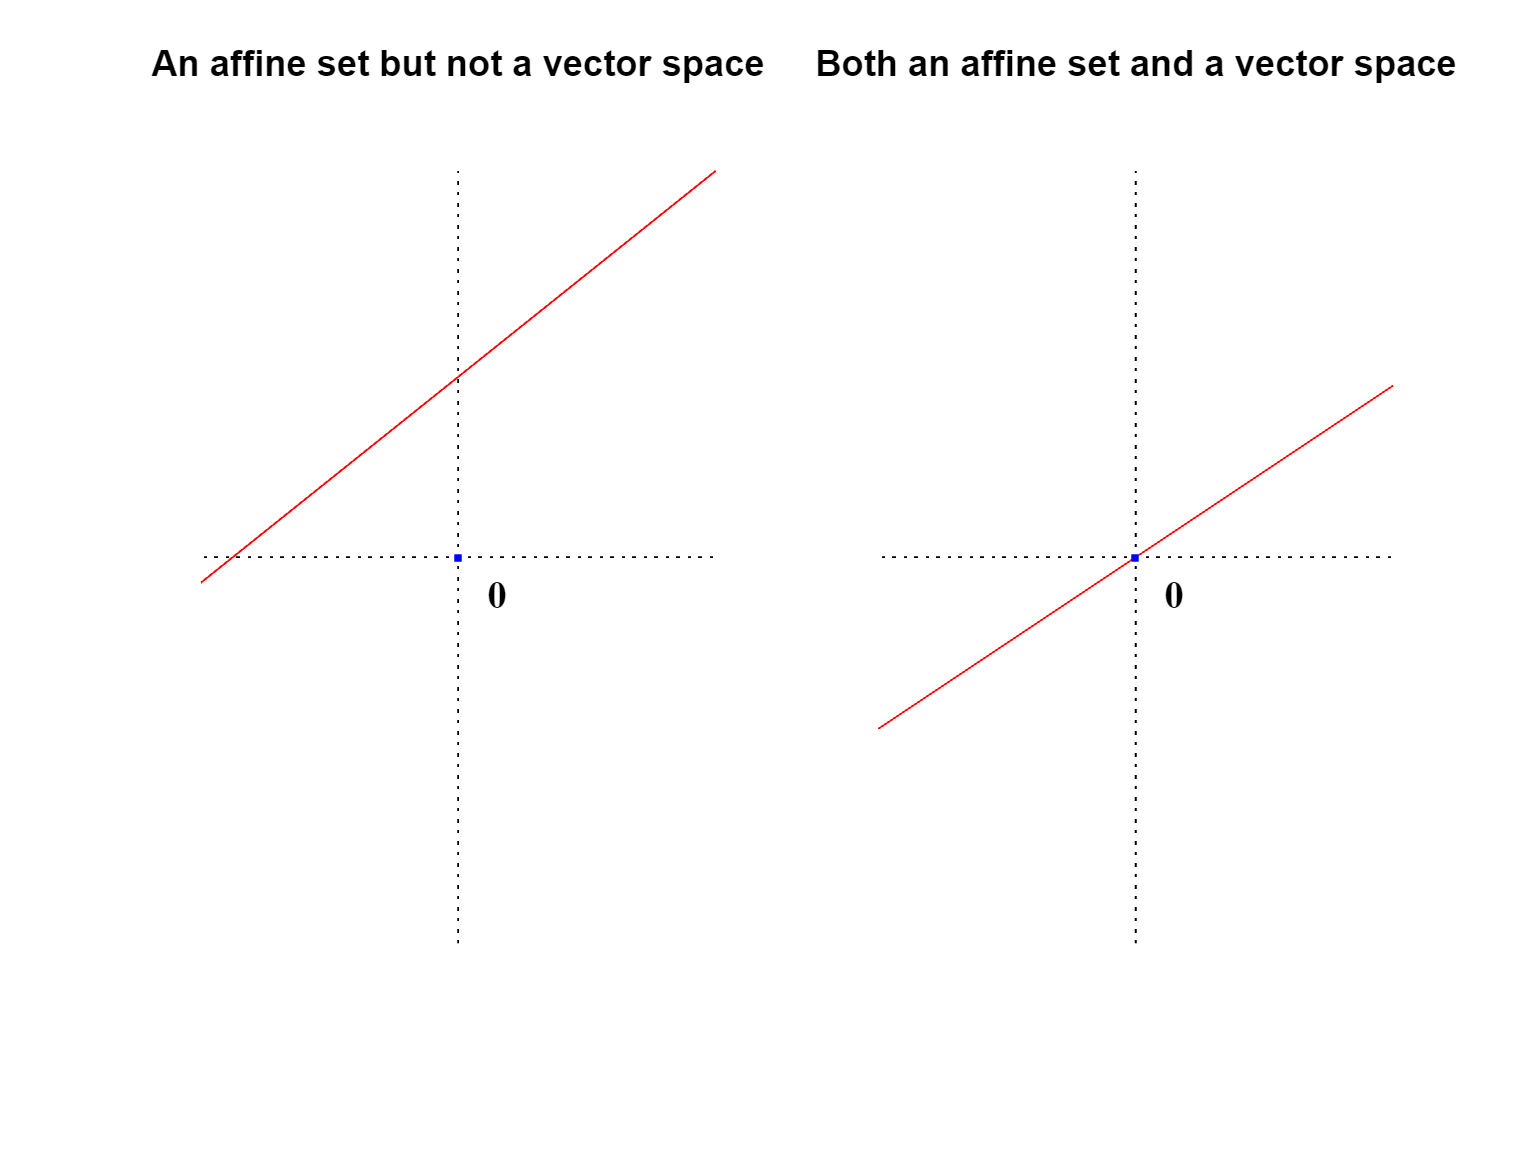

function figII6a()

subplot(1,2,1)
hold on
axis([-2 2 -2 2])
axis equal
axis off
plot([0 0],[-3 3],':k')
plot([-3 3],[0 0],':k')
plot([-3 2],[-1 3],'-r')
plot(0,0,'.b')
text(0.2, -0.3,'${\bf 0}$','Interpreter','latex')
title('An affine set but not a vector space')
subplot(1,2,2)
hold on
axis([-2 2 -2 2])
axis equal
axis off
plot([0 0],[-3 3],':k')
plot([-3 3],[0 0],':k')
plot([-3 3],[-2 2],'-r')
plot(0,0,'.b')
text(0.2, -0.3,'${\bf 0}$','Interpreter','latex')
title('Both an affine set and a vector space')
end

function figII6b()
clf
subplot(1,2,1)
hold on
axis([-3 3 -3 3])
axis square
axis off
plot([0 0],[-3 3],':k')
plot([-3 3],[0 0],':k')
plot(1,-1/2,'.b')
text(1+0.1,-1/2+0.1,'$(1,-\frac12)$','Interpreter','latex','Color','b')
text(-2,1.2,'row$(A)$','Interpreter','latex','Color','b')
plot([-3 3],[3/2 -3/2],'b')
plot(1/2,1,'.r')
text(0.7,1,'$(\frac12,1)$','Interpreter','latex','Color','r')

ans =        1             -1/2            0             -1/2     
       0              0              1              1       


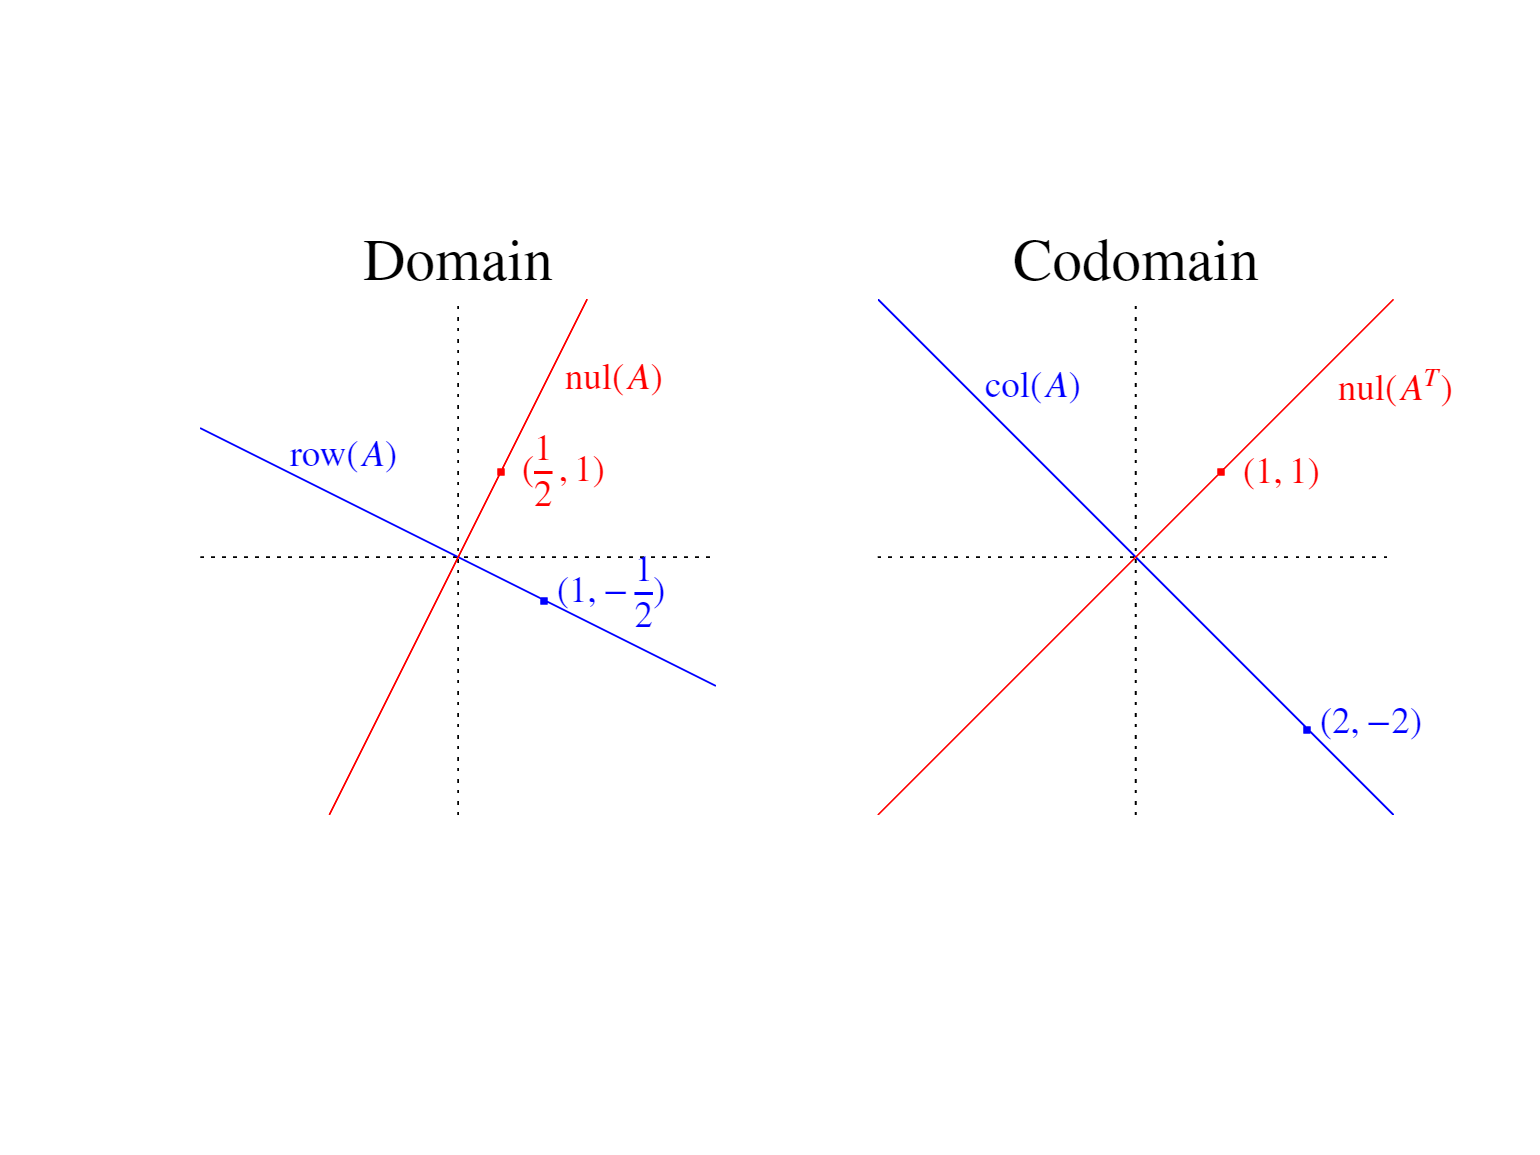

text(1.2,2.1,'nul$(A)$','Interpreter','latex','Color','r')
plot([-3/2 3/2],[-3 3],'r')
title('Domain','Interpreter','latex','FontSize',16)
subplot(1,2,2)
hold on
axis([-3 3 -3 3])

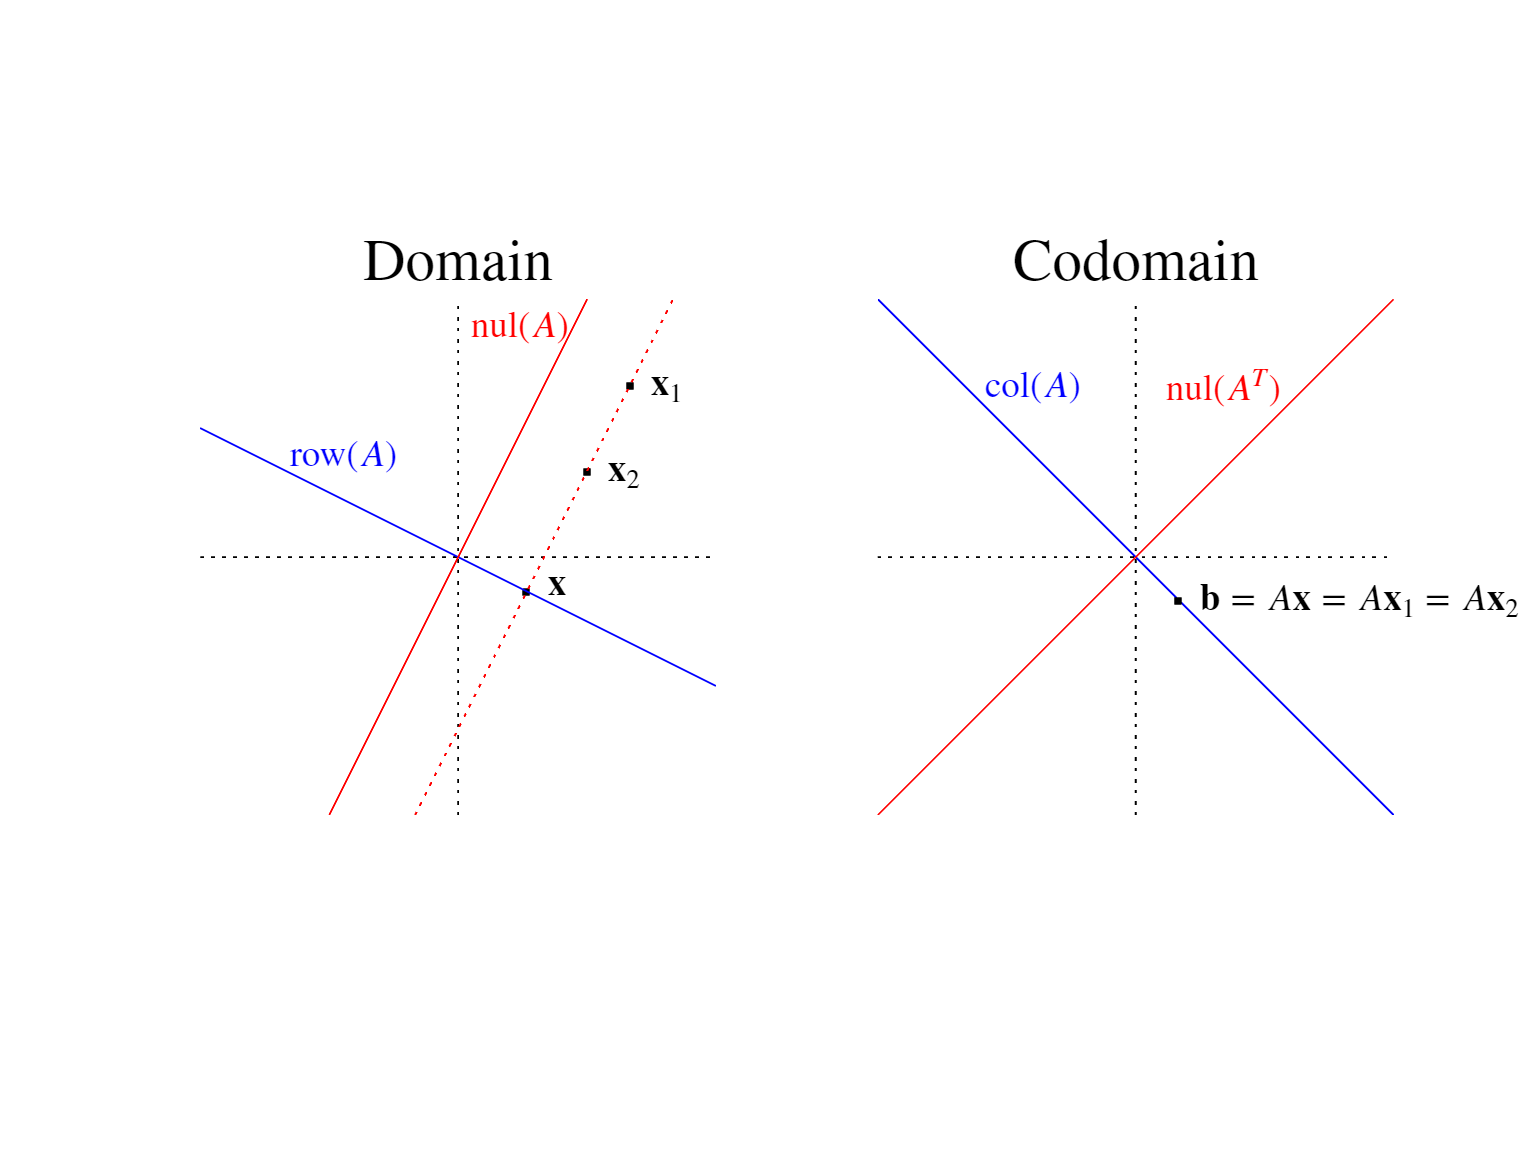

axis square
axis off
plot([0 0],[-3 3],':k')
plot([-3 3],[0 0],':k')
plot(2,-2,'.b')
text(2+0.1,-2+0.1,'$(2,-2)$','Interpreter','latex','Color','b')
text(-2+0.2,2,'col$(A)$','Interpreter','latex','Color','b')
plot([-3 3],[3 -3],'b')
plot(1,1,'.r')
text(1.2,1,'$(1,1)$','Interpreter','latex','Color','r')
text(2.3,2,'nul$(A^T)$','Interpreter','latex','Color','r')
plot([-3 3],[-3 3],'r')
title('Codomain','Interpreter','latex','FontSize',16)
end



function figII6c()
clf
subplot(1,2,1) % domain
hold on
axis([-3 3 -3 3])
axis square
axis off
plot([0 0],[-3 3],':k')     % y-axis
plot([-3 3],[0 0],':k')     % x-axis
plot(2,2,'.k')              % x1      
text(2.2,2,'${\bf x}_1$','Interpreter','latex','Color','k')
plot(3/2,1,'.k')            % x2     
text(1.7,1,'${\bf x}_2$','Interpreter','latex','Color','k')
plot(0.8,-0.4,'.k')              % x     
text(1.0,-.3,'${\bf x}$','Interpreter','latex','Color','k')
text(-2,1.2,'row$(A)$','Interpreter','latex','Color','b')
plot([-3 3],[3/2 -3/2],'b')   % row space
%plot(1/2,1,'.r')
%text(0.7,1,'$(\frac12,1)$','Interpreter','latex','Color','r')
text(0.1,2.7,'nul$(A)$','Interpreter','latex','Color','r')
plot([-3/2 3/2],[-3 3],'r')    % null space
plot([-1/2 5/2],[-3 3],':r')   % line parallel to the null space
title('Domain','Interpreter','latex','FontSize',16)
subplot(1,2,2)   % codomain
hold on
axis([-3 3 -3 3])
axis square
axis off
plot([0 0],[-3 3],':k')
plot([-3 3],[0 0],':k')
%plot(2,-2,'.b')
%text(2+0.1,-2+0.1,'$(2,-2)$','Interpreter','latex','Color','b')
text(-2+0.2,2,'col$(A)$','Interpreter','latex','Color','b')
plot([-3 3],[3 -3],'b')
plot(1/2,-1/2,'.k')   % b
text(1/2+0.2,-1/2,'${\bf b}=A{\bf x}=A{\bf x}_1=A{\bf x}_2$','Interpreter','latex','Color','k')
text(.3,2,'nul$(A^T)$','Interpreter','latex','Color','r')
plot([-3 3],[-3 3],'r')
title('Codomain','Interpreter','latex','FontSize',16)
end